tic
addpath 'C:\Users\domi1\OneDrive - Università degli Studi di Parma\Desktop\Polymers\M.Montecarlo-20240121T122014Z-001\Protein folding\Simulazioni\proteine'
amm = "DAADKSKAAKAAASSAAASADAAAKASASS"; %protein chain to analize
[amm_group,chain_lenght] = amm_to_group(amm);

% Protein_structure 
Swip = 100000;
T = 501; 
XYZ = zeros (chain_lenght,3,Swip);
E = zeros (Swip,1);
[E_old,XYZ_old] = Energy(amm_group,chain_lenght);
for i = 1:Swip
    [E_new,XYZ_new] = Energy(amm_group,chain_lenght);
    B = exp( -(E_new-E_old) / T );
    acc = min(1,B);
    if rand()<acc
       E_old = E_new;
       XYZ_old = XYZ_new;
    end
    XYZ(:,:,i) = XYZ_old;
    E(i)=E_old;
if mod(i,round(Swip/10)) == 0
    Percentual=ceil((i/Swip)*100),end
end

Percentual = 10

Percentual = 20

Percentual = 30

Percentual = 40

Percentual = 50

Percentual = 60

Percentual = 70

Percentual = 80

Percentual = 90

Percentual = 100

Energia=E

Energia =        -2200
       -2200
       -2200
       -2200
       -3800
       -3800
       -1800
       -2100
       -4700
       -4700



Idrofobici = [1.000 1.000 0.067]  ;
Acido = [1.000 0.000 0.000];
Base = [0.000 0.000 1.000];
Polare = [0.000 1.000 0.000];
toc

Elapsed time is 919.760318 seconds.


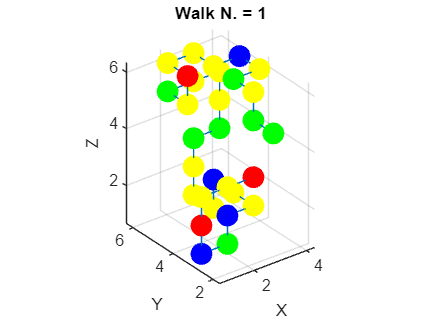

% 
figure (1)
plotSpheres(1,1/3,chain_lenght,amm_group,XYZ)

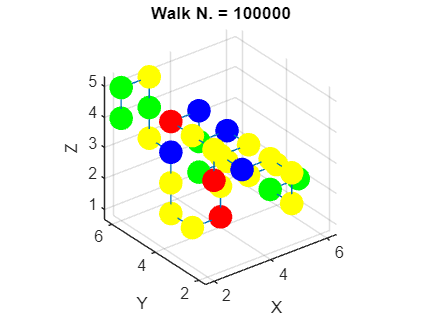


figure (2)
plotSpheres(Swip,1/3,chain_lenght,amm_group,XYZ)


Idrofobicity_start = ones(100,1);
Idrofobicity_end = ones(100,1);

parfor i = 1:100
Idrofobicity_start(i) = Idrofobic(i,chain_lenght,XYZ,amm_group);
Idrofobicity_end(i) =Idrofobic(i+(Swip-100),chain_lenght,XYZ,amm_group);
end


STD_Idrofobicity_start = std(Idrofobicity_start)

STD_Idrofobicity_start = 0.0508

Idrofobicity_start = mean(Idrofobicity_start)

Idrofobicity_start = 0.2370


STD_Idrofobicity_end = std(Idrofobicity_end)

STD_Idrofobicity_end = 1.6737e-16

Idrofobicity_end  = mean(Idrofobicity_end)

Idrofobicity_end = 0.2776